## **Load data **

% load data 1 and data 2
data_load = load("../EEG_data/FIBROP001_DD1_BL_clean.mat");
data_before_car = data_load.data_clean;
data_load_2 = load("../EEG_data/FIBROP001_DD2_150_clean.mat");
data_before_car_2 = data_load_2.data_clean;

% % (need more data from more participants --> later implement for loop)
% % load data 1 and data 2 for participant 2
% data_load_3 = load("EEG_data/FIBROP002_DD1_150_clean.mat");
% data_before_car_3 = data_load_3.data_clean;
% data_load_4 = load("EEG_data/FIBROP002_DD2_150_clean.mat");
% data_before_car_4 = data_load_4.data_clean;

% % view EEG data
% cfg = [];
% ft_databrowser(cfg, data_before_car_2);



% implement CAR re-referencing
cfg = [];
cfg.channel = 'all'; % this is the default
cfg.reref = 'yes';
cfg.refmethod = 'avg';
cfg.refchannel = 'all';
data = ft_preprocessing(cfg, data_before_car);

 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an est

data_2 = ft_preprocessing(cfg, data_before_car_2);

 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estim

freq                   = [];
freq.freqcfg           = [];
freq.freqcfg.method    = 'mtmfft';
freq.freqcfg.taper     = 'dpss';
freq.freqcfg.output    = 'fourier';
freq.freqcfg.foilim    = [8 13];
freq.freqcfg.tapsmofrq = 2;
freqdata1           = ft_freqanalysis(freq.freqcfg, data);

the input is raw data with 61 channels and 102 trials


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 102/102 nfft: 5007 samples, datalength: 820 samples, 6 tapers

the call to "ft_freqanalysis" took 16 seconds and required the additional allocation of an estimated 76 MB


% freqdata2           = ft_freqanalysis(freq.freqcfg, data_2);

freq                   = [];
freq.freqcfg           = [];
freq.freqcfg.method    = 'mtmfft';
freq.freqcfg.taper     = 'dpss';
freq.freqcfg.output    = 'powandcsd';
freq.freqcfg.tapsmofrq = 2;
freqdata_csd           = ft_freqanalysis(freq.freqcfg, data);

freqnew=ft_checkdata(freqdata1,'cmbrepresentation','full');

size(freqnew.crsspctrm)

ans =    102    61    61    51


size(mean(squeeze(freqnew.crsspctrm(1,:,:,:)), 3))

ans =     61    61


rcond(mean(squeeze(freqnew.crsspctrm(1,:,:,:)), 3))

ans = 2.3676e-19

grangercfg           = [];
grangercfg.method    = 'granger';
grangercfg.granger.svd       = true;
grangercfg.granger.stabilityfix = true;

gdata = [];
gdata.g1_bivar_reg      = ft_connectivityanalysis(grangercfg, freqdata1); % error with npad

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 58 MB
computing multivariate non-parametric spectral factorization on 61 channels


Error using zeros
Size inputs must be integers.

Error in sfactorization_wilson (line 64)
  S        = cat(3, zeros(size(S,1), size(S,1), npad), S);

Error in ft_connectivity_csd2transfer (

% gdata.g2_bivar_reg      = ft_connectivityanalysis(grangercfg, freqdata2);

conn_mat = mean(gdata.g1_bivar_reg.grangerspctrm, 3);
figure;imagesc(conn_mat);

cbh = colorbar();

grangercfg = [];
grangercfg.method  = 'granger';
grangercfg.granger.conditional = 'no';
grangercfg.granger.sfmethod = 'bivariate';

gdata = [];
gdata.g1_bivar_reg      = ft_connectivityanalysis(grangercfg, freqdata1);

the call to "ft_selectdata" took 17 seconds and required the additional allocation of an estimated 0 MB
computing pairwise non-parametric spectral factorization on 1830 channel pairs


gdata.g2_bivar_reg      = ft_connectivityanalysis(grangercfg, freqdata2);


% disp(det(residual_variance));

% Preprocessed data in FieldTrip format
% data = your_preprocessed_data;

% Define range of model orders to test
max_order = 20;
AIC_values = zeros(1, max_order);
BIC_values = zeros(1, max_order);

trial_lengths = cellfun(@(x) size(x, 2), data.trial); 
n_samples = sum(trial_lengths); % because biosig will concatenate the trials % size(data.trial{1}, 2); % Assuming consistent trial length
% N = sum(cellfun(@(x) size(x, 2), data.trial)); % Total number of time points

for order = 1:max_order
    % Fit MVAR model
    cfg = [];
    cfg.order = order;
    % cfg.keeptrial = 'yes';
    cfg.method = 'biosig'; % Or 'biosig', or another supported toolbox
    mvar = ft_mvaranalysis(cfg, data_2); % [data=>8; data_2=>5]

    num_channels = size(mvar.noisecov, 1); % Number of channels (size of noisecov matrix)
    % ridge regularization to avoid negative determinant (?)
    epsilon = 1e-6; 
    residual_variance = mvar.noisecov + epsilon * eye(size(mvar.noisecov)); % noise covariance matrix

    % Extract log-likelihood and number of parameters
    log_noisecov = log(det(residual_variance));
    log_likelihood = -0.5 * n_samples * (num_channels * log(2 * pi) + log_noisecov + num_channels); 
    num_params = order * num_channels^2;

    % Calculate AIC and BIC
    AIC_values(order) = -2 * log_likelihood + 2 * num_params;
    BIC_values(order) = -2 * log_likelihood + num_params * log(n_samples);
end

 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB



the call to "ft_mvaranalysis" took 3 seconds and required the additional allocation of an estimated 832 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 94 MB


the call to "ft_mvaranalysis" took 3 seconds and required the additional allocation of an estimated 758 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 672 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 761 M


the call to "ft_mvaranalysis" took 4 seconds and required the additional allocation of an estimated 685 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 677 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB



the call to "ft_mvaranalysis" took 4 seconds and required the additional allocation of an estimated 678 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 677 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB



the call to "ft_mvaranalysis" took 5 seconds and required the additional allocation of an estimated 678 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 680 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 777 M


the call to "ft_mvaranalysis" took 6 seconds and required the additional allocation of an estimated 681 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 683 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 775 M


the call to "ft_mvaranalysis" took 6 seconds and required the additional allocation of an estimated 683 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 682 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 776 M


the call to "ft_mvaranalysis" took 7 seconds and required the additional allocation of an estimated 683 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 680 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 775 M


the call to "ft_mvaranalysis" took 8 seconds and required the additional allocation of an estimated 681 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 684 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 779 M


the call to "ft_mvaranalysis" took 9 seconds and required the additional allocation of an estimated 682 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 687 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 777 M


the call to "ft_mvaranalysis" took 10 seconds and required the additional allocation of an estimated 686 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 683 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB



the call to "ft_mvaranalysis" took 10 seconds and required the additional allocation of an estimated 684 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 95 MB


the call to "ft_mvaranalysis" took 10 seconds and required the additional allocation of an estimated 681 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 690 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 778 M


the call to "ft_mvaranalysis" took 12 seconds and required the additional allocation of an estimated 687 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 685 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 779 M


the call to "ft_mvaranalysis" took 12 seconds and required the additional allocation of an estimated 685 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 683 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 778 M


the call to "ft_mvaranalysis" took 14 seconds and required the additional allocation of an estimated 686 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 686 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB



the call to "ft_mvaranalysis" took 14 seconds and required the additional allocation of an estimated 687 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 686 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 781 M


the call to "ft_mvaranalysis" took 15 seconds and required the additional allocation of an estimated 688 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 687 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 782 M


the call to "ft_mvaranalysis" took 16 seconds and required the additional allocation of an estimated 688 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_mvaranalysis at line 124



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_mvaranalysis at line 156

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 686 MB


 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_preprocessing at line 276
 In ft_mvaranalysis at line 274



 In ft_datatype_raw>fixtimeaxes at line 366
 In ft_datatype_raw at line 316
 In ft_checkdata at line 280
 In ft_selectdata at line 132
 In ft_preprocessing at line 319
 In ft_mvaranalysis at line 274

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 781 M


the call to "ft_mvaranalysis" took 16 seconds and required the additional allocation of an estimated 709 MB


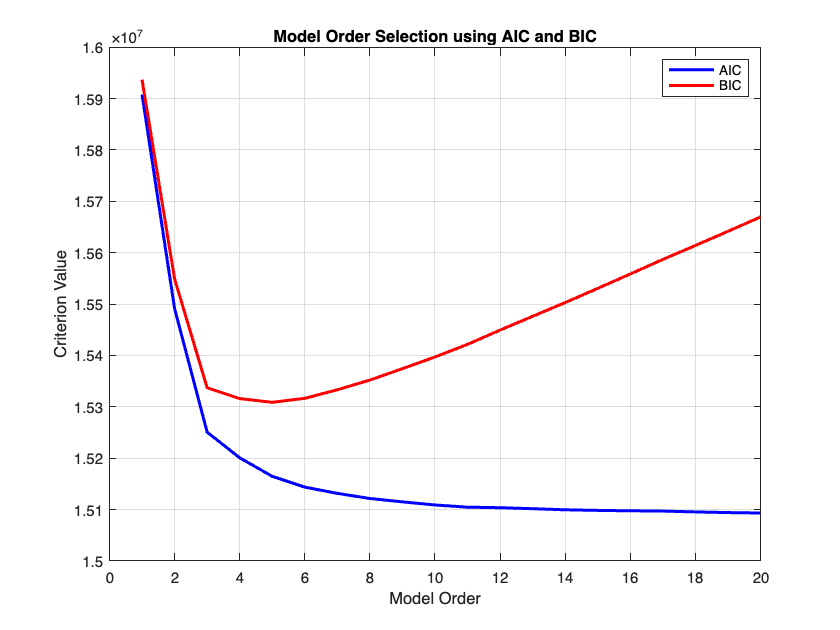

% Find the optimal order
[~, optimal_order_AIC] = min(AIC_values);
[~, optimal_order_BIC] = min(BIC_values);

% Plot AIC and BIC
figure;
plot(1:max_order, AIC_values, 'b-', 'LineWidth', 2); hold on;
plot(1:max_order, BIC_values, 'r-', 'LineWidth', 2);
legend('AIC', 'BIC');
xlabel('Model Order');
ylabel('Criterion Value');
title('Model Order Selection using AIC and BIC');
grid on;


disp(['Optimal Order (AIC): ', num2str(optimal_order_AIC)]);

Optimal Order (AIC): 20


% disp(test1);
disp(['Optimal Order (BIC): ', num2str(optimal_order_BIC)]);

Optimal Order (BIC): 5


## search for model order after downsampling

% Preprocessed data in FieldTrip format
% data = your_preprocessed_data;
cfg = [];
cfg.resamplefs = 250;
cfg.detrend = 'no';
% data_250 = ft_resampledata(cfg, data);
data_250_2 = ft_resampledata(cfg, data_2);

the input is raw data with 54 channels and 71 trials


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
resampling data


resampling data in trial 71 from 71

original sampling rate = 500 Hz
new sampling rate = 250 Hz
the call to "ft_resampledata" took 16 seconds and required the additional allocation of an estimated 374 MB



% Define range of model orders to test
max_order = 20;
AIC_values = zeros(1, max_order);
BIC_values = zeros(1, max_order);

trial_lengths = cellfun(@(x) size(x, 2), data.trial); 
n_samples = sum(trial_lengths); % because biosig will concatenate the trials % size(data.trial{1}, 2); % Assuming consistent trial length
% N = sum(cellfun(@(x) size(x, 2), data.trial)); % Total number of time points

for order = 1:max_order
    % Fit MVAR model
    cfg = [];
    cfg.order = order;
    cfg.keeptrial = 'yes';
    cfg.method = 'biosig'; % Or 'biosig', or another supported toolbox
    mvar = ft_mvaranalysis(cfg, data_250_2); % [data_250=>7; data_250_2=>7]

    num_channels = size(mvar.noisecov, 1); % Number of channels (size of noisecov matrix)
    % ridge regularization to avoid negative determinant (?)
    epsilon = 1e-6; 
    residual_variance = mvar.noisecov + epsilon * eye(size(mvar.noisecov)); % noise covariance matrix

    % Extract log-likelihood and number of parameters
    log_noisecov = log(det(residual_variance));
    log_likelihood = -0.5 * n_samples * (num_channels * log(2 * pi) + log_noisecov + num_channels); 
    num_params = order * num_channels^2;

    % Calculate AIC and BIC
    AIC_values(order) = -2 * log_likelihood + 2 * num_params;
    BIC_values(order) = -2 * log_likelihood + num_params * log(n_samples);
end

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 89 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 89 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 89 MB



the call to "ft_mvaranalysis" took 1 seconds and required the additional allocation of an estimated 200 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 383 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 385 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 385 MB



the call to "ft_mvaranalysis" took 1 seconds and required the additional allocation of an estimated 381 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 380 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 382 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 380 MB



the call to "ft_mvaranalysis" took 1 seconds and required the additional allocation of an estimated 380 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 341 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 342 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 341 MB



the call to "ft_mvaranalysis" took 2 seconds and required the additional allocation of an estimated 340 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 341 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 341 MB



the call to "ft_mvaranalysis" took 2 seconds and required the additional allocation of an estimated 340 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 341 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 343 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 343 MB



the call to "ft_mvaranalysis" took 2 seconds and required the additional allocation of an estimated 341 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 342 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 343 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 342 MB



the call to "ft_mvaranalysis" took 2 seconds and required the additional allocation of an estimated 342 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 343 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 346 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 346 MB



the call to "ft_mvaranalysis" took 3 seconds and required the additional allocation of an estimated 343 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 345 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 345 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 345 MB



the call to "ft_mvaranalysis" took 3 seconds and required the additional allocation of an estimated 343 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 339 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 339 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 339 MB



the call to "ft_mvaranalysis" took 3 seconds and required the additional allocation of an estimated 344 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 344 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 345 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 344 MB



the call to "ft_mvaranalysis" took 4 seconds and required the additional allocation of an estimated 344 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 344 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 344 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 344 MB



the call to "ft_mvaranalysis" took 4 seconds and required the additional allocation of an estimated 347 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 345 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 345 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 345 MB



the call to "ft_mvaranalysis" took 4 seconds and required the additional allocation of an estimated 345 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 345 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 346 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 345 MB



the call to "ft_mvaranalysis" took 5 seconds and required the additional allocation of an estimated 346 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 348 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 350 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 350 MB



the call to "ft_mvaranalysis" took 5 seconds and required the additional allocation of an estimated 346 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 346 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 346 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 346 MB



the call to "ft_mvaranalysis" took 5 seconds and required the additional allocation of an estimated 346 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 347 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 347 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 347 MB



the call to "ft_mvaranalysis" took 5 seconds and required the additional allocation of an estimated 346 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 347 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 347 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 347 MB



the call to "ft_mvaranalysis" took 6 seconds and required the additional allocation of an estimated 346 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 347 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 347 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 347 MB



the call to "ft_mvaranalysis" took 6 seconds and required the additional allocation of an estimated 346 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 347 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 347 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 347 MB



the call to "ft_mvaranalysis" took 6 seconds and required the additional allocation of an estimated 348 MB


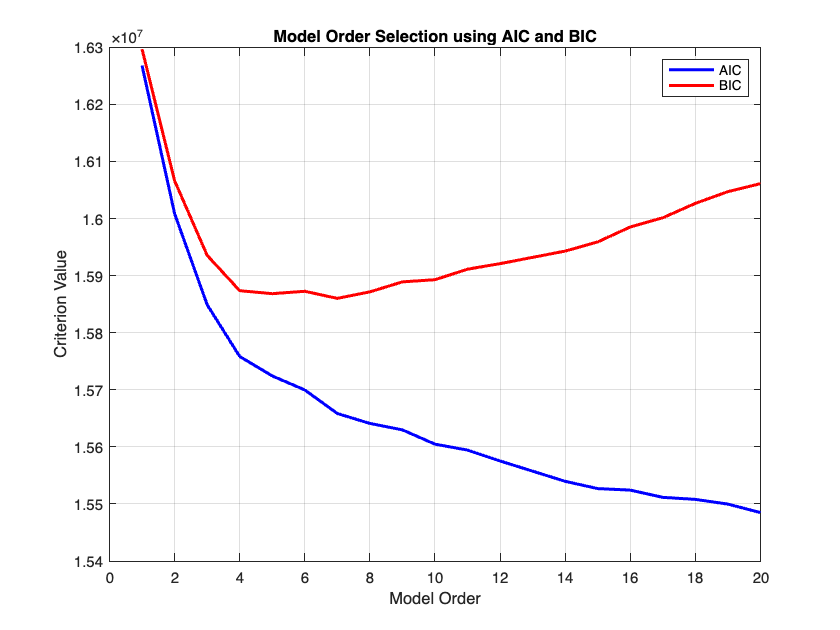


% Find the optimal order
[~, optimal_order_AIC] = min(AIC_values);
[~, optimal_order_BIC] = min(BIC_values);

% Plot AIC and BIC
figure;
plot(1:max_order, AIC_values, 'b-', 'LineWidth', 2); hold on;
plot(1:max_order, BIC_values, 'r-', 'LineWidth', 2);
legend('AIC', 'BIC');
xlabel('Model Order');
ylabel('Criterion Value');
title('Model Order Selection using AIC and BIC');
grid on;


disp(['Optimal Order (AIC): ', num2str(optimal_order_AIC)]);

Optimal Order (AIC): 20


% disp(test1);
disp(['Optimal Order (BIC): ', num2str(optimal_order_BIC)]);

Optimal Order (BIC): 7


## search for model order WITHOUT CAR method re-referencing


% Define range of model orders to test
max_order = 20;
AIC_values = zeros(1, max_order);
BIC_values = zeros(1, max_order);

trial_lengths = cellfun(@(x) size(x, 2), data.trial); 
n_samples = sum(trial_lengths); % because biosig will concatenate the trials % size(data.trial{1}, 2); % Assuming consistent trial length
% N = sum(cellfun(@(x) size(x, 2), data.trial)); % Total number of time points

for order = 1:max_order
    % Fit MVAR model
    cfg = [];
    cfg.order = order;
    cfg.keeptrial = 'yes';
    cfg.method = 'biosig'; % Or 'biosig', or another supported toolbox
    mvar = ft_mvaranalysis(cfg, data_before_car_2); % [data_before_car=>8; data_before_car_2=>5]

    num_channels = size(mvar.noisecov, 1); % Number of channels (size of noisecov matrix)
    % ridge regularization to avoid negative determinant (?)
    epsilon = 1e-6; 
    residual_variance = mvar.noisecov + epsilon * eye(size(mvar.noisecov)); % noise covariance matrix

    % Extract log-likelihood and number of parameters
    log_noisecov = log(det(residual_variance));
    log_likelihood = -0.5 * n_samples * (num_channels * log(2 * pi) + log_noisecov + num_channels); 
    num_params = order * num_channels^2;

    % Calculate AIC and BIC
    AIC_values(order) = -2 * log_likelihood + 2 * num_params;
    BIC_values(order) = -2 * log_likelihood + num_params * log(n_samples);
end

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 392 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 188 MB



the call to "ft_mvaranalysis" took 1 seconds and required the additional allocation of an estimated 940 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 769 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 863 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 862 MB



the call to "ft_mvaranalysis" took 2 seconds and required the additional allocation of an estimated 767 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 762 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 859 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 859 MB



the call to "ft_mvaranalysis" took 2 seconds and required the additional allocation of an estimated 763 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 677 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 774 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 774 MB



the call to "ft_mvaranalysis" took 3 seconds and required the additional allocation of an estimated 678 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 678 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 774 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 774 MB



the call to "ft_mvaranalysis" took 4 seconds and required the additional allocation of an estimated 680 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 95 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 113 MB



the call to "ft_mvaranalysis" took 4 seconds and required the additional allocation of an estimated 681 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 683 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 775 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 775 MB



the call to "ft_mvaranalysis" took 5 seconds and required the additional allocation of an estimated 684 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 683 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 776 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 775 MB



the call to "ft_mvaranalysis" took 5 seconds and required the additional allocation of an estimated 684 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 683 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 777 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 776 MB



the call to "ft_mvaranalysis" took 6 seconds and required the additional allocation of an estimated 684 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 683 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 777 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 777 MB



the call to "ft_mvaranalysis" took 6 seconds and required the additional allocation of an estimated 685 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 91 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 113 MB



the call to "ft_mvaranalysis" took 7 seconds and required the additional allocation of an estimated 687 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 686 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 778 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 778 MB



the call to "ft_mvaranalysis" took 8 seconds and required the additional allocation of an estimated 686 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 95 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 113 MB



the call to "ft_mvaranalysis" took 8 seconds and required the additional allocation of an estimated 685 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 685 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 779 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 778 MB



the call to "ft_mvaranalysis" took 9 seconds and required the additional allocation of an estimated 688 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 687 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 781 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 780 MB



the call to "ft_mvaranalysis" took 9 seconds and required the additional allocation of an estimated 687 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 686 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 780 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 780 MB



the call to "ft_mvaranalysis" took 10 seconds and required the additional allocation of an estimated 687 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 686 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 780 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 780 MB



the call to "ft_mvaranalysis" took 11 seconds and required the additional allocation of an estimated 686 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 687 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 781 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 781 MB



the call to "ft_mvaranalysis" took 12 seconds and required the additional allocation of an estimated 687 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 688 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 782 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 782 MB



the call to "ft_mvaranalysis" took 13 seconds and required the additional allocation of an estimated 687 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 687 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 783 MB
preprocessing
preprocessing trial 71 from 71

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 782 MB



the call to "ft_mvaranalysis" took 13 seconds and required the additional allocation of an estimated 689 MB


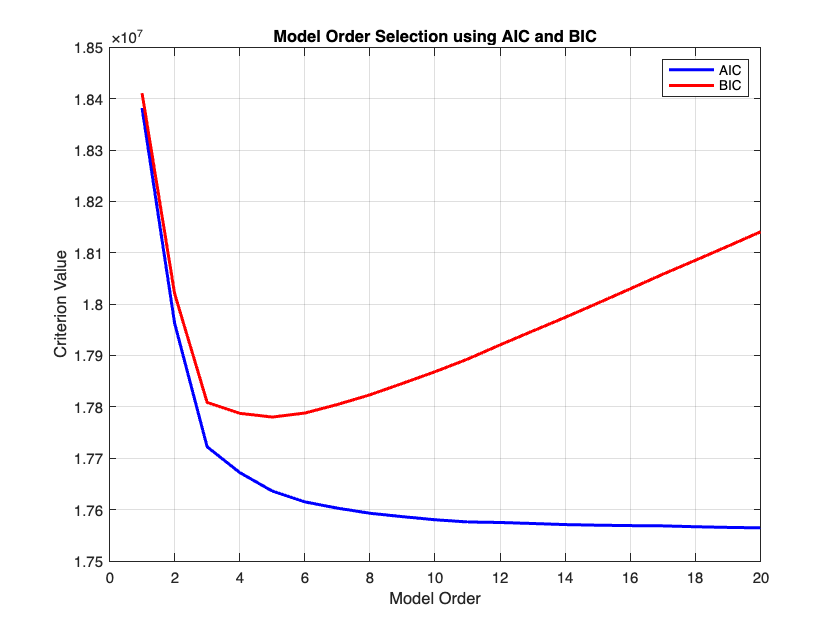


% Find the optimal order
[~, optimal_order_AIC] = min(AIC_values);
[~, optimal_order_BIC] = min(BIC_values);

% Plot AIC and BIC
figure;
plot(1:max_order, AIC_values, 'b-', 'LineWidth', 2); hold on;
plot(1:max_order, BIC_values, 'r-', 'LineWidth', 2);
legend('AIC', 'BIC');
xlabel('Model Order');
ylabel('Criterion Value');
title('Model Order Selection using AIC and BIC');
grid on;


disp(['Optimal Order (AIC): ', num2str(optimal_order_AIC)]);

Optimal Order (AIC): 20


% disp(test1);
disp(['Optimal Order (BIC): ', num2str(optimal_order_BIC)]);

Optimal Order (BIC): 5


% % Example: Selecting optimal order using ARFIT toolbox
% [~,~,order] = arfit(data.trial, 1, 20); % Search for order between 1 and 20
% disp(['Optimal order: ', num2str(order)]);

% cov_matrix = cov(data_resampled.trial{1}');
% disp(eig(cov_matrix)); % Check eigenvalues

% % Inspect trial data passed to ft_mvaranalysis
% disp(size(data_resampled.trial{1})); % Should show [num_channels, num_samples]
% disp(var(data_resampled.trial{1}, 0, 2)); % Variance across channels

cfg = [];
cfg.order = 8; % Define model order
cfg.method = 'biosig'; % % Use the biosig toolbox (FieldTrip default)

mdata = ft_mvaranalysis(cfg, data);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 102 from 102

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 90 MB



the call to "ft_mvaranalysis" took 6 seconds and required the additional allocation of an estimated 647 MB


mdata_2 = ft_mvaranalysis(cfg, data_2);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 569 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 572 MB
preprocessing
preprocessing trial 86 from 86

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an estimated 572 MB



the call to "ft_mvaranalysis" took 7 seconds and required the additional allocation of an estimated 570 MB


int_chan_labels = cellstr(intersect(string(data.label), string(data_2.label)));

cfg        = [];
cfg.method = 'mvar';
cfg.foilim    = [8 13];
% cfg.channel   = int_chan_labels;

mfreq      = ft_freqanalysis(cfg, mdata);

the input is mvar data
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
computing MAR-model based TFR
processing timewindow 1 from 1

the call to "ft_freqanalysis_mvar" took 0 seconds and required the additional allocation of an estimated 81 MB


mfreq_2      = ft_freqanalysis(cfg, mdata_2);

the input is mvar data
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 9 MB
computing MAR-model based TFR
processing timewindow 1 from 1

the call to "ft_freqanalysis_mvar" took 0 seconds and required the additional allocation of an estimated 40 MB



% %% compute granger causality connectivity
% cfg           = [];
% cfg.method    = 'granger';
% cfg.granger.sfmethod = 'bivariate';
% granger      = ft_connectivityanalysis(cfg, mvar_data);

cfg           = [];
cfg.method    = 'granger';
granger       = ft_connectivityanalysis(cfg, mfreq);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 15 MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated 15 MB


granger_2       = ft_connectivityanalysis(cfg, mfreq_2);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 32 MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated 32 MB


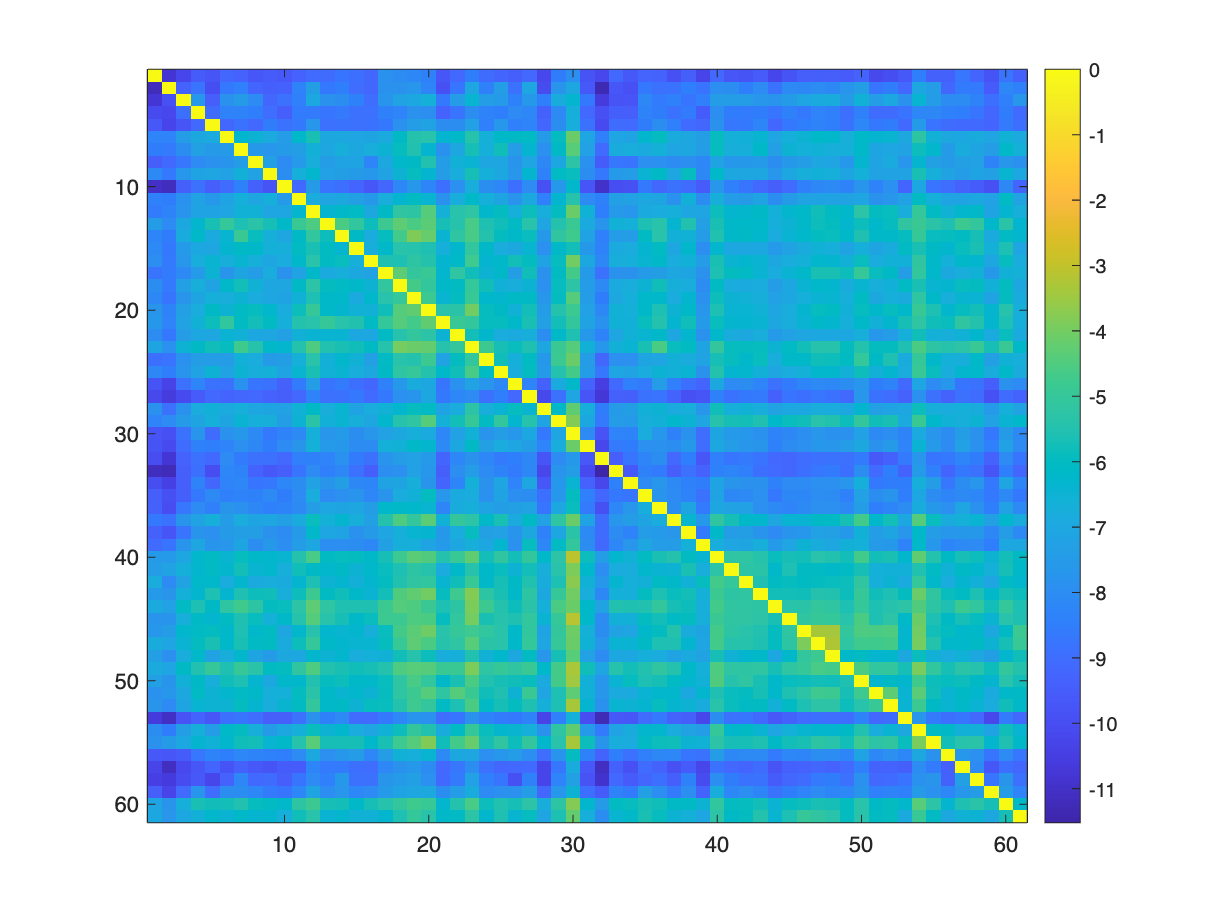

conn_mat = mean(granger.grangerspctrm, 3);
figure;imagesc(conn_mat);
cbh = colorbar();

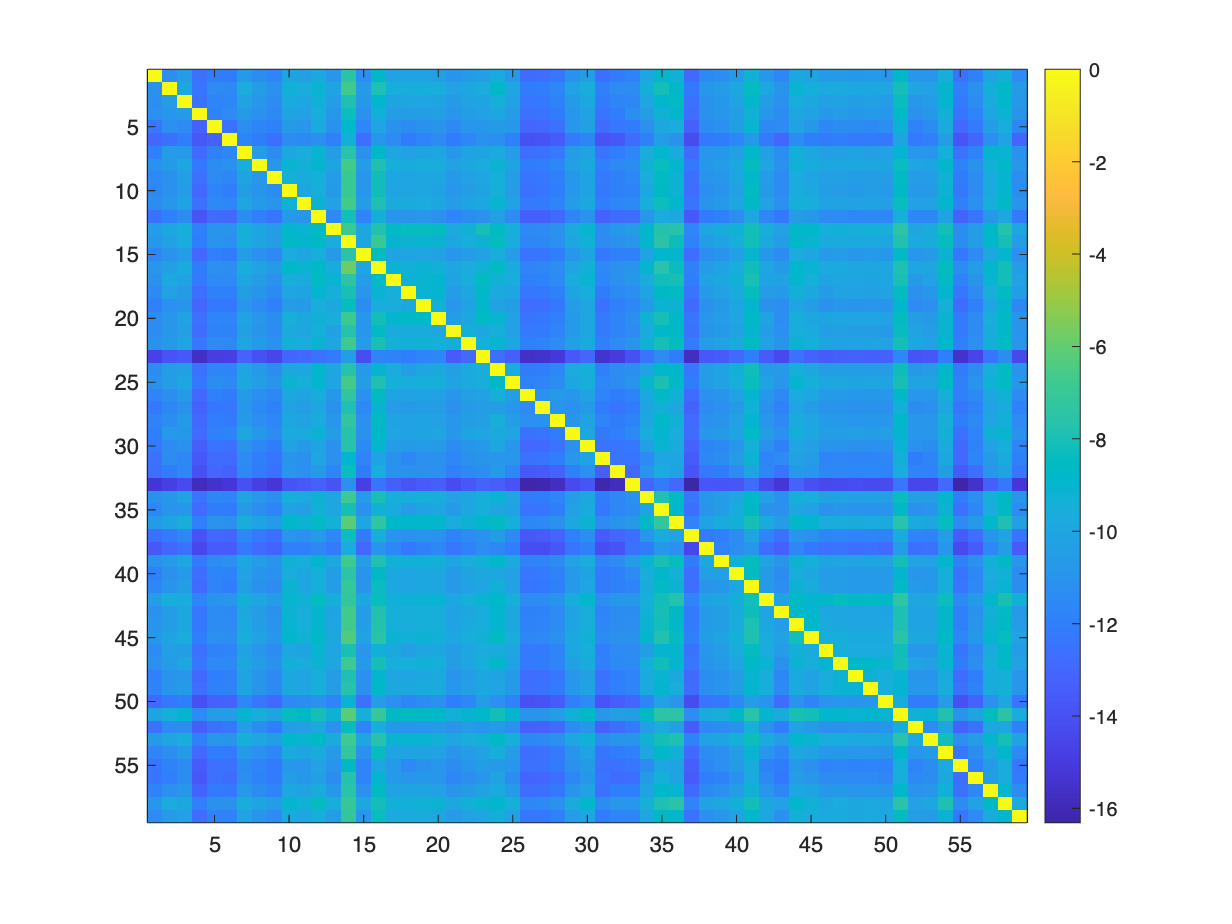

conn_mat_2 = mean(granger_2.grangerspctrm, 3);
figure;imagesc(conn_mat_2);
cbh = colorbar();

% diff_conn_mat = conn_mat_2 - conn_mat;
% figure;imagesc(diff_conn_mat);
% cbh = colorbar();


labels_mask = ~ismember(granger.label, int_chan_labels);
labels_mask_2 = ~ismember(granger_2.label, int_chan_labels);

% labels_mask_mat = repmat(labels_mask, 1, size(labels_mask, 1));
% labels_mask_mat = and(labels_mask_mat, labels_mask_mat.');
% labels_mask_mat_2 = repmat(labels_mask_2, 1, size(labels_mask_2, 1));
% labels_mask_mat_2 = and(labels_mask_mat_2, labels_mask_mat_2.');

des_conn_mat = mean(granger.grangerspctrm, 3);
% Apply the mask to rows
des_conn_mat(labels_mask, :) = NaN;
% Apply the mask to columns
des_conn_mat(:, labels_mask) = NaN;

% conn_mat = conn_mat(labels_mask_mat);
% [I, J] = find(labels_mask_mat);
% des_conn_mat(I)   = conn_mat(sub2ind(size(conn_mat), I, J));
% des_conn_mat      = des_conn_mat(:);
figure;imagesc(des_conn_mat);
xlabel('To Node');
ylabel('From Node');
cbh = colorbar();

des_conn_mat_2 = mean(granger_2.grangerspctrm, 3);
% Apply the mask to rows
des_conn_mat_2(labels_mask_2, :) = NaN;
% Apply the mask to columns
des_conn_mat_2(:, labels_mask_2) = NaN;

figure;imagesc(des_conn_mat_2);
xlabel('To Node');
ylabel('From Node');
cbh = colorbar();
% diff_conn_mat = des_conn_mat_2 - des_conn_mat;
% figure;imagesc(diff_conn_mat);

% cbh = colorbar();

% Create a logical mask for non-NaN values
nonNaNMask = ~labels_mask;
% Extract only the non-NaN values
conn_mat = des_conn_mat(nonNaNMask, nonNaNMask);

% Create a logical mask for non-NaN values
nonNaNMask = ~labels_mask_2;
% Extract only the non-NaN values
conn_mat_2 = des_conn_mat_2(nonNaNMask, nonNaNMask);

diff_conn_mat = conn_mat_2 - conn_mat;
figure;imagesc(diff_conn_mat);
xlabel('To Node');
ylabel('From Node');
cbh = colorbar();